ave_bound = 20; % average bound
p = 1; 
t = 1; 
ymin = -1.5; 
ymax = 1.5;% contants
anno = -0.35; 
interval = 20;

x_dim = 21; % important to adapt image dimension
y_dim = 21;

data_x = Cucirc3MHz11334X; % Matrix input
data_y = Cucirc3MHz11334Y;
data_w = Cucirc3MHz11334W;

data_length_x = size(data_x, 1);

% process_lorentzian_fits(x_dim, y_dim,data_x,data_y,data_w)
[xmidMatrix, ymidMatrix, rMatrix, phiMatrix] = lorentzian_fit(x_dim, y_dim, data_length_x, data_x, data_y, data_w, 0);

%imgY = process_image_single2(PID) % If we not use Lorentzian feating function 

imgY = process_image_single2(ymidMatrix);

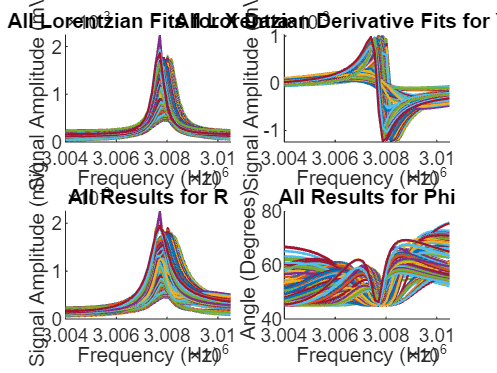

%imgPhi = process_image_single2(phiMatrix);
%imgX = process_image_single2(xmidMatrix);
%imgR = process_image_single2(rMatrix);

%imgY = grad3(imgY);
%imgX = grad3(imgX);
%imgPhi = grad3(imgPhi);
%imgR = grad3(imgR);

%detectCircleInImage(imgY)
%interpo22(imgY, ave_bound, p, t, ymin, ymax, anno, interval)

h = 0.1; % Example value for h
a = 2; % Example value for a
R = 0.1; % Example value for R

%sigma = evaluate_conductivity(x_dim, y_dim, data_length_x, data_x, data_y, data_w, h, a, R);


% Exemple de données (Ces données doivent être définies selon votre cas spécifique)
B_matrix = imgX;  % Matrice simulée du champ magnétique
sigma = 5.8e7;              % Conductivité du cuivre en Siemens/m
thickness = 0.02;           % Épaisseur en mètres
omega = 2 * pi * 300000;        % Fréquence angulaire pour 50 Hz

% Calcul de la densité de courant pour chaque point
currentMatrix = calculate_eddy_currents(B_matrix, sigma, thickness, omega);

% Vecteurs de coordonnées pour l'affichage
xVec = 1:21;  % Vecteurs pour les axes X
yVec = 1:21;  % Vecteurs pour les axes Y

% Affichage de la distribution des courants de Foucault
display_eddy_current_distribution(xVec, yVec, B_matrix, currentMatrix);

function process_lorentzian_fits(x_dim, y_dim,data_x,data_y,data_w)
    data_length_x = size(data_x, 1);
    total_pixels = x_dim * y_dim;
    [xmidMatrix, ymidMatrix, rMatrix, phiMatrix] = lorentzian_fit(x_dim, y_dim, data_length_x, data_x, data_y, data_w, 0);
end

function [xmidMatrix, ymidMatrix, rMatrix, phiMatrix] = lorentzian_fit(x_dim, y_dim, data_length_x, data_x, data_y, data_w, display_plots)
    xmidMatrix = zeros(x_dim, y_dim);
    ymidMatrix = zeros(x_dim, y_dim);
    rMatrix = zeros(x_dim, y_dim);
    phiMatrix = zeros(x_dim, y_dim);
    
    if display_plots == 1
        figure;
        subplot(2,2,1); 
        title('All Lorentzian Fits for X Data');
        xlabel('Frequency (Hz)');
        ylabel('Signal Amplitude (mV)');
        hold on;

        subplot(2,2,2); 
        title('All Lorentzian Derivative Fits for Y Data');
        xlabel('Frequency (Hz)');
        ylabel('Signal Amplitude (mV)');
        hold on;

        subplot(2,2,3); % Pour R data
        title('All Results for R');
        xlabel('Frequency (Hz)');
        ylabel('Signal Amplitude (mV)');
        hold on;

        subplot(2,2,4); % Pour Phi data
        title('All Results for Phi');
        xlabel('Frequency (Hz)');
        ylabel('Angle (Degrees)');
        hold on;
    end

    for i = 1:x_dim
        for j = 1:y_dim
            linear_index = (i-1) * y_dim + j;
            if linear_index > data_length_x
                warning('Index %d exceeds total number of pixels %d. Skipping this pixel.', linear_index, data_length_x);
                continue;
            end
            x_data_pixel = data_x(linear_index, :);
            y_data_pixel = data_y(linear_index, :);
            w_data_pixel = data_w(linear_index, :);

            p0 = [0.018, 3008000, 1000, 0]; % Lorentzian
            p0_derivative = [0.01, 3007500, 1000, 0]; % Lorentzian derivative

            % Option settings for lsqcurvefit
            options = optimset('Display', 'off');

            % Fit Lorentzian model directly within the loop
            [p1, ~] = lsqcurvefit(@(p,x) p(1) * p(3)^2 ./ (p(3)^2 + (x - p(2)).^2) + p(4), ...
                                  p0, w_data_pixel, x_data_pixel, [], [], options);

            % Fit Lorentzian derivative model directly within the loop
            [p2, ~] = lsqcurvefit(@(p,x) p(1) * p(3) * (x - p(2)) ./ (p(3)^2 + (x - p(2)).^2) + p(4), ...
                                  p0_derivative, w_data_pixel, y_data_pixel, [], [], options);

            xmid = p1(1) * p1(3)^2 / (p1(3)^2 + (p2(1) - p1(2))^2) + p1(4);
            ymid = p2(1) * p2(3) * (p2(2) - p2(2)) / (p2(3)^2 + (p2(2) - p2(2))^2) + p2(4);
            r = sqrt(xmid^2 + ymid^2);
            phi = atan2(p2(1) * p2(3) * (p2(2) - p2(2)) / (p2(3)^2 + (p2(2) - p2(2))^2) + p2(4),p1(1) * p1(3)^2 / (p1(3)^2 + (p2(1) - p1(2))^2) + p1(4));

            xmidMatrix(i, j) = xmid;
            ymidMatrix(i, j) = ymid;
            rMatrix(i, j) = r;
            phiMatrix(i, j) = phi;

            if display_plots == 1
                subplot(2,2,1);
                plot(w_data_pixel, p1(1) * p1(3)^2 ./ (p1(3)^2 + (w_data_pixel - p1(2)).^2) + p1(4), 'LineWidth', 1);

                subplot(2,2,2);
                plot(w_data_pixel, p2(1) * p2(3) * (w_data_pixel - p2(2)) ./ (p2(3)^2 + (w_data_pixel - p2(2)).^2) + p2(4), 'LineWidth', 1);

                subplot(2,2,3);
                plot(w_data_pixel, sqrt((p1(1) * p1(3)^2 ./ (p1(3)^2 + (w_data_pixel - p1(2)).^2) + p1(4)).*(p1(1).* p1(3).^2 ./ (p1(3).^2 + (w_data_pixel - p1(2)).^2) + p1(4)) + (p2(1).* p2(3).* (w_data_pixel - p2(2)) ./ (p2(3)^2 + (w_data_pixel - p2(2)).^2) + p2(4)).*(p2(1).* p2(3).* (w_data_pixel - p2(2)) ./ (p2(3).^2 + (w_data_pixel - p2(2)).^2) + p2(4))), 'LineWidth', 1);

                subplot(2,2,4);
                plot(w_data_pixel, atan2(sqrt((p1(1) * p1(3)^2 ./ (p1(3).^2 + (w_data_pixel - p1(2)).^2) + p1(4)).^2 + (p2(1).* p2(3).* (w_data_pixel - p2(2)) ./ (p2(3).^2 + (w_data_pixel - p2(2)).^2) + p2(4)).^2), p1(1) * p1(3).^2 ./ (p1(3).^2 + (w_data_pixel - p1(2)).^2) + p1(4)) * (180/pi), 'LineWidth', 1); % Conversion en degrés
            end
        end
    end
    if display_plots == 1
        for k = 1:4
            subplot(2,2,k);
            hold off; 
        end
    end
end

function filtered_img = gaussian_filter(img, sigma, padding)
    % Create a Gaussian filter
    size = 2 * ceil(3 * sigma) + 1; % 3 sigma rule
    h = fspecial('gaussian', size, sigma);
    
    % Pad the image based on the specified padding type
    switch padding
        case 'nearest'
            img_padded = padarray(img, [ceil(size/2), ceil(size/2)], 'replicate', 'both');
        otherwise
            error('Unsupported padding type');
    end
    
    % Apply the Gaussian filter
    filtered_img = conv2(img_padded, h, 'same');
    
    % Remove the padding
    filtered_img = filtered_img(ceil(size/2)+1:end-ceil(size/2), ceil(size/2)+1:end-ceil(size/2));
end


function imgX = process_image_single2(X)
    [l, w] = size(X);
    
    imgX = zeros(l, w);
    for i = 1:l
        for j = 1:w
            if mod(i, 2) == 0
                imgX(i, j) = X(i, j);
            else
                imgX(i, j) = X(i, w + 1 - j);
            end
        end
    end
    imgX = rot90(imgX);
    imgX = gaussian_filter(imgX, 1, 'nearest');
    %imgX = imgaussfilt(imgX, 0.7);
    %Optionally: code to display the image can be uncommented to view the result
    figure;
    imagesc(imgX); % Display the matrix imgX as an image
    colormap(jet); % Set the colormap to 'jet'
    colorbar; % Add a colorbar to the side to show the scale of values
    axis image; % Set axis scaling to image to keep the correct aspect ratio
    title('Processed Image X'); % Set the title of the subplot
end


function [imgX, imgY, imgR, imgPhi] = process_image4(X, Y, R, Phi)
    [l, w] = size(X);
    imgX = zeros(l, w);
    for i = 1:l
        for j = 1:w
            if mod(i, 2) == 0
                imgX(i, j) = X(i, j);
            else
                imgX(i, j) = X(i, w + 1 - j);
            end
        end
    end
    imgX = imgaussfilt(rot90(imgX), 0.7);
    imgY = zeros(l, w);
    for i = 1:l
        for j = 1:w
            if mod(i, 2) == 0
                imgY(i, j) = Y(i, j);
            else
                imgY(i, j) = Y(i, w + 1 - j);
            end
        end
    end
    imgY = rot90(imgY);
    imgY = imgaussfilt(imgY, 0.7); % Filtre gaussien avec sigma = 1

    % Traitement de la matrice R
    imgR = zeros(l, w);
    for i = 1:l
        for j = 1:w
            if mod(i, 2) == 0
                imgR(i, j) = R(i, j);
            else
                imgR(i, j) = R(i, w + 1 - j);
            end
        end
    end
    imgR = rot90(imgR);
    imgR = imgaussfilt(imgR, 1); % Filtre gaussien avec sigma = 1

    % Traitement de la matrice Phi
    imgPhi = zeros(l, w);
    for i = 1:l
        for j = 1:w
            if mod(i, 2) == 0
                imgPhi(i, j) = Phi(i, j);
            else
                imgPhi(i, j) = Phi(i, w + 1 - j);
            end
        end
    end
    imgPhi = rot90(imgPhi);
    imgPhi = imgaussfilt(imgPhi, 1); % Filtre gaussien avec sigma = 1
end

function interpo22(image, ave_bound, p, t, ymin, ymax, anno,interval)
    % Assuming image is a matrix of intensity values
    [height, width] = size(image);  

    % Scale for plotting
    x_scale = linspace(-width, width, width);
    y_scale = linspace(-height, height, height);

    % Prepare data for interpolation
    y = ave(image, ave_bound);  % Ensure ave function calculates correctly
    x = linspace(-width, width, length(y));  % Match length of y
    %f3 = fit(x', y', 'pchipinterp');  % Cubic interpolation
    f3 = fit(x', y', 'cubicinterp');  % Cubic interpolation

    % Fine-grained x for smooth plotting
    x_s = linspace(-width, width,50);
    y_s = feval(f3, x_s);

    % Smoothing the data
    y_smooth = smooth(y_s, 5);

    % Create figure
    figure;
    set(gcf, 'Position', [100, 100, 1200, 600]);  % Adjust size as needed
    subplot(1, 2, 1);

    % Plotting the image
    imagesc(x_scale, y_scale, image);
    colormap('jet');
    colorbar;
    xlabel('X position (pixels)');
    ylabel('Y position (pixels)');
    title('Processed Image');

    % Peak and trough detection using derivative
    subplot(1, 2, 2);
    plot(x_s, y_smooth, 'LineWidth', 1.5);
    hold on;

    % Segmenting the x-axis and finding max/min within segments
    leftSegmentIndex = x_s >= -width & x_s < 0;
    rightSegmentIndex = x_s >= 0 & x_s <= width;

    % Maximum and minimum in the left segment
    [maxLeft, idxMaxLeft] = max(y_s(leftSegmentIndex));
    [minLeft, idxMinLeft] = min(y_s(leftSegmentIndex));
    xMaxLeft = x_s(leftSegmentIndex);
    xMinLeft = x_s(leftSegmentIndex);

    % Maximum and minimum in the right segment
    [maxRight, idxMaxRight] = max(y_s(rightSegmentIndex));
    [minRight, idxMinRight] = min(y_s(rightSegmentIndex));
    xMaxRight = x_s(rightSegmentIndex);
    xMinRight = x_s(rightSegmentIndex);

    % Plotting max/min points
    plot(xMaxLeft(idxMaxLeft), maxLeft, 'ro', 'DisplayName', 'Max Left');
    plot(xMinLeft(idxMinLeft), minLeft, 'bo', 'DisplayName', 'Min Left');
    plot(xMaxRight(idxMaxRight), maxRight, 'ro', 'DisplayName', 'Max Right');
    plot(xMinRight(idxMinRight), minRight, 'bo', 'DisplayName', 'Min Right');

    % Calculate distances between midpoints of max/min pairs and plot a line
        % Calculate distances between midpoints of max/min pairs
    midpoint1 = (xMaxLeft(idxMaxLeft) + xMinLeft(idxMinLeft)) / 2;
    midpoint2 = (xMaxRight(idxMaxRight) + xMinRight(idxMinRight)) / 2;
    distance = abs(midpoint2 - midpoint1);  % Distance along x-axis

    % Plot and annotate the distance
    plot([midpoint1 midpoint2], [0, 0], 'k--', 'LineWidth', 2);  % Plot a line between midpoints
    text(mean([midpoint1, midpoint2]), 0, sprintf('Distance: %.2f mm', distance), ...
         'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'BackgroundColor', 'white', 'FontSize', 12);


    %     % Calculate the first derivative
    % dy = diff(y_smooth) ./ diff(x_s);
    % x_s_mid = (x_s(1:end-1) + x_s(2:end)) / 2;  % Midpoints for derivative
    % 
    % % Find zero crossings of the derivative (indicating peaks and troughs)
    % sign_dy = sign(dy);
    % zero_crossings = diff(sign_dy);
    % 
    % % Peaks: -1 to 1 transition
    % peaks = find(zero_crossings == -2) + 1;
    % % Troughs: 1 to -1 transition
    % troughs = find(zero_crossings == 2) + 1;
    % 
    % % Remove points within the specified interval
    % peaks = remove_close_points(peaks, interval);
    % troughs = remove_close_points(troughs, interval);
    % 
    % % Ensure there are enough points to select
    % if length(peaks) < p+2 || length(troughs) < t+2
    %     error('Not enough peaks or troughs found with the given interval');
    % end
    % 
    % % Select the desired peaks and troughs
    % selected_peaks = peaks(p:p+1);
    % selected_troughs = troughs(t:t+1);
    % 
    % % Plot detected peaks and troughs
    % if ~isempty(selected_peaks)
    %     plot(x_s_mid(selected_peaks), y_smooth(selected_peaks), 'ro', 'DisplayName', 'Peaks');
    % end
    % if ~isempty(selected_troughs)
    %     plot(x_s_mid(selected_troughs), y_smooth(selected_troughs), 'bo', 'DisplayName', 'Troughs');
    % end
    % 
    % % Calculate distances between midpoints of max/min pairs
    % if ~isempty(selected_peaks) && ~isempty(selected_troughs)
    %     midpoint1 = (x_s_mid(selected_peaks(1)) + x_s_mid(selected_troughs(1))) / 2;
    %     midpoint2 = (x_s_mid(selected_peaks(2)) + x_s_mid(selected_troughs(2))) / 2;
    %     distance = abs(midpoint2 - midpoint1);  % Distance along x-axis
    % 
    %     % Plot and annotate the distance
    %     plot([midpoint1 midpoint2], [0, 0], 'k--', 'LineWidth', 2);  % Plot a line between midpoints
    %     text(mean([midpoint1, midpoint2]), 0, sprintf('Distance: %.2f mm', distance), ...
    %         'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'BackgroundColor', 'white', 'FontSize', 12);
    % end
    % 
    % % Calculate the first derivative
    % dy = diff(y_smooth) ./ diff(x_s);
    % x_s_mid = (x_s(1:end-1) + x_s(2:end)) / 2;  % Midpoints for derivative
    % 
    % % Find zero crossings of the derivative (indicating peaks and troughs)
    % sign_dy = sign(dy);
    % zero_crossings = diff(sign_dy);
    % 
    % % Peaks: -1 to 1 transition
    % peaks = find(zero_crossings == -2) + 1;
    % % Troughs: 1 to -1 transition
    % troughs = find(zero_crossings == 2) + 1;
    % 
    % % Boundary checks
    % peaks(peaks > length(x_s_mid)) = [];
    % troughs(troughs > length(x_s_mid)) = [];
    % 
    % % Plot detected peaks and troughs
    % if ~isempty(peaks)
    %     plot(x_s_mid(peaks), y_smooth(peaks), 'ro', 'DisplayName', 'Peaks');
    % end
    % if ~isempty(troughs)
    %     plot(x_s_mid(troughs), y_smooth(troughs), 'bo', 'DisplayName', 'Troughs');
    % end
    % 
    % % Calculate distances between midpoints of max/min pairs
    % if ~isempty(peaks) && ~isempty(troughs)
    %     midpoint1 = (x_s_mid(peaks(1)) + x_s_mid(troughs(1))) / 2;
    %     if length(peaks) > 1 && length(troughs) > 1
    %         midpoint2 = (x_s_mid(peaks(2)) + x_s_mid(troughs(2))) / 2;
    %     else
    %         midpoint2 = midpoint1; % If no second pair, use the same midpoint
    %     end
    %     distance = abs(midpoint2 - midpoint1);  % Distance along x-axis
    % 
    %     % Plot and annotate the distance
    %     plot([midpoint1 midpoint2], [0, 0], 'k--', 'LineWidth', 2);  % Plot a line between midpoints
    %     text(mean([midpoint1, midpoint2]), 0, sprintf('Distance: %.2f pixels', distance), ...
    %         'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'BackgroundColor', 'white', 'FontSize', 12);
    % end

    % Annotations for distances
    legend show;
    xlim([-width width]);
    xlabel('X position (pixels)');
    ylabel('Signal Intensity');
    hold off;
end


function arr = ave(image, bound)
    % Crée un nouveau tableau arr de taille correspondant au nombre de colonnes de l'image et l'initialise à 0.
    arr = zeros(1, size(image, 2));
    % Boucle à travers les colonnes de la matrice d'image et calcule la valeur moyenne des cellules dans les limites spécifiées.
    for i = 1:size(image, 2)
        sum_column = 0;
        count = 0;
        for j = max(1, 10-bound+1):min(size(image, 1), 10+bound+1)
            sum_column = sum_column + image(j, i);
            count = count + 1;
        end
        arr(i) = sum_column / count;
    end
end

function filtered_points = remove_close_points(points, interval)
    % Remove points that are too close to each other
    filtered_points = points;
    i = 2;
    while i <= length(filtered_points)
        if filtered_points(i) - filtered_points(i-1) < interval
            filtered_points(i) = NaN;
        end
        i = i + 1;
    end
    filtered_points = filtered_points(~isnan(filtered_points));
end

function processed_data = grad3(data)
    % Used to flatten the scanned image when there's a gradient in the fundamental signal levels
    % along either x or y position axes.
    
    [jj, ii] = size(data);
    
    % grad1: gradient along the x-axis, starting from the middle-right edge to the middle-left edge.
    grad1 = linspace(0, mean(mean(data(1:2, ii))) - mean(mean(data(1:2, 1:2))), ii);
    % grad2: gradient along the y-axis, starting from the bottom-left edge to the top-left edge.
    grad2 = linspace(0, mean(mean(data(jj-1:jj, 1:2))) - mean(mean(data(1:2, 1:2))), jj)';
    % grad3: gradient along the x-axis, starting from the bottom-right edge to the bottom-left edge.
    grad3 = linspace(0, mean(mean(data(jj-1:jj, ii-1:ii))) - mean(mean(data(jj-1:jj, 1:2))), ii);
    % grad4: gradient along the y-axis, starting from the bottom-right edge to the top-right edge.
    grad4 = linspace(0, mean(mean(data(jj-1:jj, ii-1:ii))) - mean(mean(data(1:2, ii-1:ii))), jj)';
    
    % Creates a 2D array grad of the same shape as the input data, and fills it with the calculated gradient values.
    grad = zeros(jj, ii);
    for xs = 1:jj
        for ys = 1:ii
            grad(xs, ys) = data(xs, ys) - (grad1(ys) + grad3(ys)) / 2 + (grad2(xs) + grad4(xs)) / 2;
        end
    end
    
    % Subtracts the flipped grad array from the input data to obtain the processed data.
    processed_data = data - fliplr(grad);
    % % Display the processed dat
    % figure;
    % imagesc(processed_data); % Display the matrix imgX as an image
    % colormap(jet); % Set the colormap to 'jet'
    % colorbar; % Add a colorbar to the side to show the scale of values
    % axis image; % Set axis scaling to image to keep the correct aspect ratio
    % title('Processed Image X'); % Set the title of the subplot
end

function processed_data = grad(data)
    % Used to flatten the scanned image when there's a gradient in the fundamental signal levels
    % along either x or y position axes.
    [jj, ii] = size(data);
    
    % grad1: gradient along the x-axis, starting from the middle-right edge to the middle-left edge.
    grad1 = linspace(0, mean(mean(data(1:2, ii))) - mean(mean(data(1:2, 1:2))), ii);
    % grad2: gradient along the y-axis, starting from the bottom-left edge to the top-left edge.
    grad2 = linspace(0, mean(mean(data(jj-1:jj, 1:2))) - mean(mean(data(1:2, 1:2))), jj)';
    % grad3: gradient along the x-axis, starting from the bottom-right edge to the bottom-left edge.
    grad3 = linspace(0, mean(mean(data(jj-1:jj, ii-1:ii))) - mean(mean(data(jj-1:jj, 1:2))), ii);
    % grad4: gradient along the y-axis, starting from the bottom-right edge to the top-right edge.
    grad4 = linspace(0, mean(mean(data(jj-1:jj, ii-1:ii))) - mean(mean(data(1:2, ii-1:ii))), jj)';
    
    % Creates a 2D array grad of the same shape as the input data, and fills it with the calculated gradient values.
    grad = zeros(jj, ii);
    for xs = 1:jj
        for ys = 1:ii
            grad(xs, ys) = data(xs, ys) - (grad1(ys) + grad3(ys)) / 2 + (grad2(xs) + grad4(xs)) / 2;
        end
    end
    
    % Subtracts the flipped grad array from the input data to obtain the processed data.
    processed_data = data - fliplr(grad);
        % Limiting the values to the range [-10, 10] and replacing outliers with the mean of their neighbors
    for i = 1:jj
        for j = 1:ii
            if processed_data(i, j) > 6 || processed_data(i, j) < -6 % If problems on some points use this and change it
                % Define the neighborhood bounds
                imin = max(i-1, 1);
                imax = min(i+1, jj);
                jmin = max(j-1, 1);
                jmax = min(j+1, ii);

                % Get the neighborhood values excluding the current outlier point
                neighborhood = processed_data(imin:imax, jmin:jmax);
                neighborhood = neighborhood(neighborhood >= -6 & neighborhood <= 10);

                % Calculate the mean of the neighborhood
                if ~isempty(neighborhood)
                    processed_data(i, j) = mean(neighborhood);
                else
                    processed_data(i, j) = 0; % Fallback to 0 if no valid neighbors
                end
            end
        end
    end
end

% Plot the gradients
function plot_gradients(image, gradComponents)
    figure;
    subplot(2, 2, 1);
    imagesc(image);
    title('Original Image');
    colorbar;

    subplot(2, 2, 2);
    imagesc(gradComponents.gradX);
    title('Gradient in X Direction');
    colorbar;

    subplot(2, 2, 3);
    imagesc(gradComponents.gradY);
    title('Gradient in Y Direction');
    colorbar;

    subplot(2, 2, 4);
    imagesc(gradComponents.combinedGrad);
    title('Combined Gradient');
    colorbar;

    % Adjust layout for better visualization
    set(gcf, 'Position', [100, 100, 800, 600]);
    colormap jet;  % Consistent colormap for better comparison
end


function r2 = r_squared(y_true, y_pred)
    total_variance = sum((y_true - mean(y_true)).^2);
    explained_variance = sum((y_pred - y_true).^2);
    r2 = 1 - (explained_variance / total_variance);
end

% Function to load data
function data = loadData(path)
    data = readmatrix(path, 'Delimiter', ' ');
end

% Function to delete data
function data = deleteData(path)
    data = readmatrix(path, 'Delimiter', ' ');
    data(:, 1:25) = []; % Adjust as needed based on actual data structure
end

function y = lorentzian(x, A, xo, gamma, C)
    y = A * gamma^2 ./ (gamma^2 + (x - xo).^2) + C;
    disp(['Size of output y: ', num2str(length(y)), ' and input x: ', num2str(length(x))]);  % Debugging output sizes
end

% Lorentzian derivative function
function y = lorentzian_derivative(x, A, x0, gamma, C)
    y = A * gamma * (x - x0) ./ (gamma^2 + (x - x0).^2) + C;
end

function plotLocalGradients(gradX, gradY, magnitude, direction)
    figure;
    
    subplot(2, 2, 1);
    imagesc(gradX);
    title('Gradient X');
    colorbar;
    
    subplot(2, 2, 2);
    imagesc(gradY);
    title('Gradient Y');
    colorbar;
    
    subplot(2, 2, 3);
    imagesc(magnitude);
    title('Gradient Magnitude');
    colorbar;
    
    subplot(2, 2, 4);
    imagesc(direction);
    title('Gradient Direction');
    colorbar;

    colormap jet;
    set(gcf, 'Position', [100, 100, 800, 800]);  % Adjust size for clarity
end

function [gradX, gradY, magnitude, direction] = computeLocalGradients(data)
    [jj, ii] = size(data);
    gradX = zeros(jj, ii);
    gradY = zeros(jj, ii);
    for i = 2:(jj-1)
        for j = 2:(ii-1)
            gradX(i, j) = (data(i, j+1) - data(i, j-1)) / 2;
            gradY(i, j) = (data(i+1, j) - data(i-1, j)) / 2;
        end
    end
    magnitude = sqrt(gradX.^2 + gradY.^2);
    direction = atan2(gradY, gradX);  % Retourne l'angle en radians

end


function plotResults(xmidMatrix, ymidMatrix, rMatrix, phiMatrix)
    figure;
    subplot(2, 2, 1); imagesc(xmidMatrix); title('Amplitude'); colorbar;
    subplot(2, 2, 2); imagesc(ymidMatrix); title('Position'); colorbar;
    subplot(2, 2, 3); imagesc(rMatrix); title('Width'); colorbar;
    subplot(2, 2, 4); imagesc(phiMatrix); title('Offset'); colorbar;
    colormap jet; 
end

function process_matrix_diagonals()
    % Initialize matrix dimensions
    rows = 41;
    cols = 39;

    % Generate a random matrix and adjust its size
    matrix = randn(rows, cols);
    matrix = matrix(1:39, 1:39);

    % Initialize arrays to store trace values
    traces_main_diag = [];
    traces_other_diag = [];

    % Process the main diagonal
    temp_matrix = matrix;
    while size(temp_matrix, 1) > 0 && size(temp_matrix, 2) > 0
        trace_value = trace(temp_matrix);
        traces_main_diag = [traces_main_diag, trace_value];
        temp_matrix = temp_matrix(1:end-1, 2:end); % Crop first row and last column
    end

    % Process the other diagonal (flip the matrix first)
    temp_matrix = flipud(matrix);
    while size(temp_matrix, 1) > 0 && size(temp_matrix, 2) > 0
        trace_value = trace(temp_matrix);
        traces_other_diag = [traces_other_diag, trace_value];
        temp_matrix = temp_matrix(1:end-1, 2:end); % Crop first row and last column
    end

    % Create diagonal matrices from trace values
    trace_matrix_main_diag = diag(traces_main_diag);
    trace_matrix_other_diag = diag(traces_other_diag);

    % Display the trace matrices as images
    figure;
    subplot(1, 2, 1);
    imagesc(trace_matrix_main_diag);
    colorbar;
    title('Trace Values for Main Diagonal');

    subplot(1, 2, 2);
    imagesc(trace_matrix_other_diag);
    colorbar;
    title('Trace Values for Other Diagonal');
end

function detectCircleInImage(img)
    % Load the image data
    img = double(img(:, :, 1)); % Extract the red channel and convert to double

    % Normalize the image
    img = (img - min(img(:))) / (max(img(:)) - min(img(:)));

    % Adjusted threshold to ensure we're focusing on very red regions
    threshold = 0.95; % Higher threshold for more intense red regions
    binaryImage = img > threshold;

    % Find the center and radius of the circle using only the most intense regions
    [rows, columns] = size(binaryImage);
    [columnsInImage, rowsInImage] = meshgrid(1:columns, 1:rows);
    centerX = mean(columnsInImage(binaryImage));
    centerY = mean(rowsInImage(binaryImage));
    radius = sqrt(sum(binaryImage(:)) / pi);

    % Image dimensions in pixels and real-world dimensions in mm
    imgWidthPixels = columns;  % Width of the image in pixels
    imgWidthMM = 42;           % Total width of the image in mm (-21 to 21 mm)

    % Conversion factor from pixels to mm
    pixelToMM = imgWidthMM / imgWidthPixels;

    % Calculate diameter in pixels and convert to mm
    diameterPixels = 2 * radius;
    diameterMM = diameterPixels * pixelToMM;

    % Display the original image
    figure;
    subplot(1, 2, 1);
    imshow(img, []);
    title('Original Image');
    hold on;

    % Plotting the circle
    theta = linspace(0, 2*pi, 100);
    x = centerX + radius * cos(theta);
    y = centerY + radius * sin(theta);
    plot(x, y, 'r-', 'LineWidth', 2);
    text(centerX, centerY - radius - 5, sprintf('Diameter: %.2f mm', diameterMM), 'Color', 'yellow', 'FontSize', 12, 'HorizontalAlignment', 'center');
    hold off;

    % Display the binary image with the detected circle
    subplot(1, 2, 2);
    imshow(binaryImage);
    title('Binary Image with Detected Circle');
    hold on;
    plot(x, y, 'g-', 'LineWidth', 2);
    text(centerX, centerY - radius - 5, sprintf('Diameter: %.2f mm', diameterMM), 'Color', 'yellow', 'FontSize', 12, 'HorizontalAlignment', 'center');
    hold off;
end

function sigma = evaluate_conductivity(x_dim, y_dim, data_length_x, data_x, data_y, data_w, h, a, R)
    % Initialize constants
    mu0 = 4 * pi * 10^(-7); % Permeability of free space
    epsilon0 = 8.854 * 10^(-12); % Permittivity of free space
    omega = 2 * pi * 3000000; % Angular frequency for 4 MHz
    epsilon_r = 1; % Example relative permittivity, adjust as necessary
        % Calculate geometric constant A
    A = (h / 4) * ((2 * a^2 + R^2) / sqrt(a^2 + R^2) - 2 * a);

    % Calculate the Lorentzian fits and matrices
    [xmidMatrix, ymidMatrix, rMatrix, phiMatrix] = lorentzian_fit(x_dim, y_dim, data_length_x, data_x, data_y, data_w, 0);

    % Calculate the conductivity sigma
    sigma = -(rMatrix / (A * mu0 * omega)) - (omega * epsilon0 * epsilon_r);

    % Display the calculated conductivity
    figure;
    imagesc(sigma);
    colormap(jet);
    colorbar;
    axis image;
    title('Calculated Conductivity \sigma');
end

function J = calculate_eddy_currents(B, sigma, d, omega)
    % B : Amplitude du champ magnétique en Tesla
    % sigma : Conductivité électrique du matériau (Siemens/m)
    % d : Épaisseur du matériau (m)
    % omega : Fréquence angulaire du champ magnétique (rad/s)
    
    % Calcul de la densité de courant de Foucault (J) basée sur la formule simplifiée
    % J = sigma * B * omega * d
    J = sigma * B * omega * d;
end

function display_eddy_current_distribution(xVec, yVec, Z, currentMatrix)
    % xVec, yVec : Vecteurs des coordonnées pour chaque axe
    % Z : Image d'arrière-plan ou champ de mesure
    % currentMatrix : Matrice des densités de courant calculées
    figure;
    imagesc(xVec, yVec, Z); % Affiche le champ magnétique ou autre paramètre
    hold on;
    % Superpose la carte des courants de Foucault
    contour(xVec, yVec, currentMatrix, 'LineColor', 'b', 'LineWidth', 2);  % Change la couleur des lignes de contour en bleu
    colorbar;
    title('Eddy Current Distribution');
    xlabel('X Coordinate');
    ylabel('Y Coordinate');
    hold off;
end
